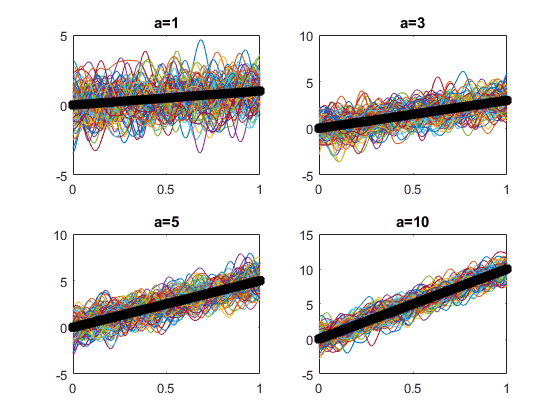

clear
clc
rng(1)

x = 0:0.01:1; x=x';
n = size(x,1);

set = [1,3,5,10];

for j = 1:4
%meanfunc = @meanConst; m = set(j); hyp_mean = m;
meanfunc = @meanLinear; a = set(j); hyp_mean = a;

covfunc = @covSEiso; ell = 0.04; sf = 1; hyp_cov = log([ell,sf]);

M = feval(meanfunc,hyp_mean,x);
C = feval(covfunc,hyp_cov,x);

[u,s,~] = svd(C);  %SVD decomposition, C=usv'

N_sample = 100;


subplot(2,2,j)
for i = 1:N_sample
    gn = randn(n,1);  % Genearate a sample from standard normal distribution
    z_gp = u*sqrt(s)*gn + M; 
    plot(x,z_gp)
    hold on
end
plot(x,M,'k*','LineWidth',3)
title(['a=',num2str(a)])
end